## BECS4 Optimization Methods Final Project

#### Introduction

The detection and classification of handwritten digits is a very common task for the introduction to neural networks. For this project we use a prewritten neural network workflow from [Johannes Langelaar](https://ch.mathworks.com/matlabcentral/profile/authors/8723697)

The mnist data on handwritten digits is already preprocessed and ready to use.

Mathworks: https://ch.mathworks.com/matlabcentral/fileexchange/90461-neural-network-training-with-adam-optimizer-from-scratch/?s_tid=LandingPageTabfx

Originaly there are **60'000** digits to train the model and **10'000** for testing. To increase the difficulty and have a better comparability between methods, only **20'000** digits were used for training and **5000** for testing. 

**Explanation for the usage of genetic algorithms in neural networks**

https://towardsdatascience.com/gas-and-nns-6a41f1e8146d

### NN-Architecture

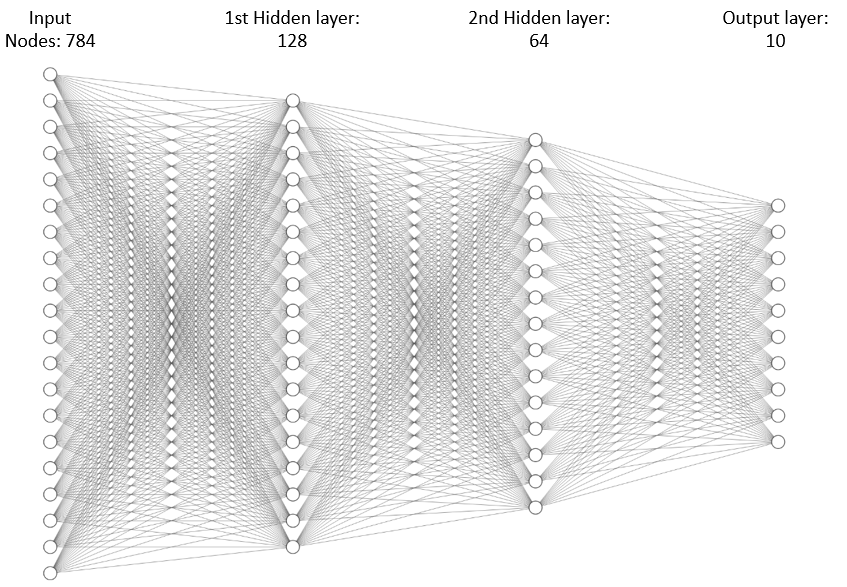

#### Input digits (28X28)

#### Project goal:

The first goal of the project is to evaluate different optimization methods to imporve the backpropagation of the model. The methods used are:

- Gradient descent 

- Mini-batch gradient descent 

- Stochastic gradient descent -X

- Adagrad. -X

- Adadelta. -X     

- RMSprop.

- Adam. -X

The second goal is to implement a genetic algorithm which finds the best initial weights for the first hidden layer to increase the accuracy. 

As a workflow template we use the publication of Ecer et al. https://www.mdpi.com/1099-4300/22/11/1239

The following steps were implemented:

- Train 10 individual models over 3 epochs with random weights. 

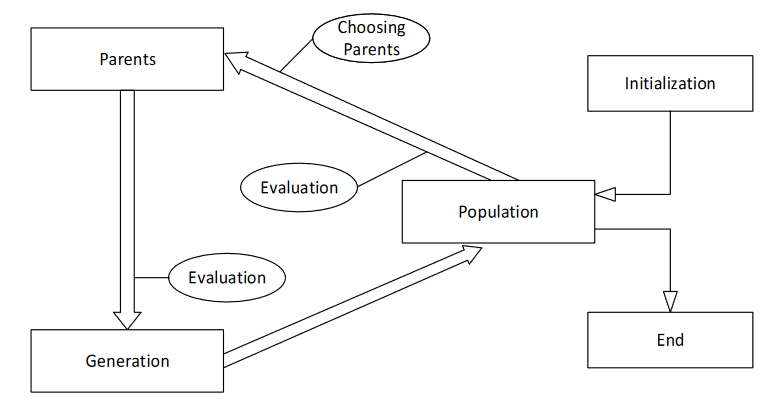

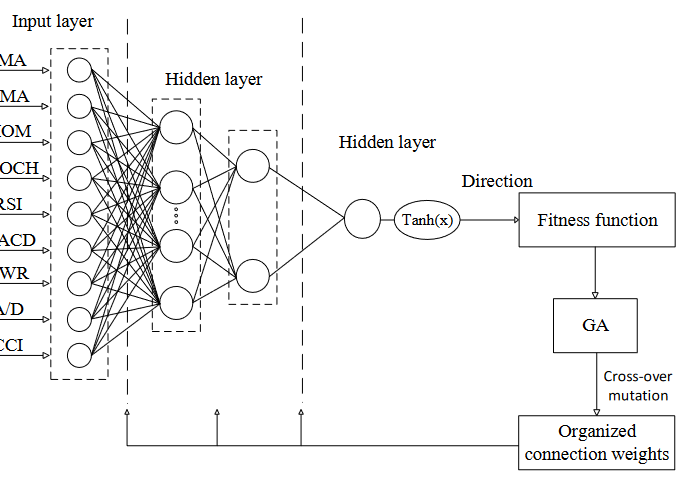

#### Data preprocessing

%cd 'C:\Users\kevin yar\OneDrive - ZHAW\KEVIN STUFF\ZHAW\_PYTHON_R\_GITHUB\becs4\neural_network_mninst'
cd neural_network_mninst\

%% training data
disp('Loading data...')

% load train data
train_data = load('mnist_train.csv');

%reduce data volume to increase difficulty
train_data = train_data(1:10000,:);

%start progress bar
f = waitbar(0, 'Starting');

labels = train_data(:,1);
y = zeros(10,length(train_data)); % output labels for training
for i = 1:length(train_data)
    waitbar(i/length(train_data), f, sprintf('Training Data: %d %%', floor(i/length(train_data)*100)));
    %one hot encoding
    y(labels(i)+1,i) = 1;
end
close(f)
% preprocessing
images = train_data(:,2:785);
images = images/255;
images = images'; % Input vectors for training

%% test data
    
% load test data
test_data = load('mnist_test.csv');
%reduce test data
test_data = test_data(1:5000, :);

%progress bar
f = waitbar(0, 'Starting');

test_labels = test_data(:,1);
test_y = zeros(10 ,length(test_data));
for i = 1:length(test_data)
    waitbar(i/length(test_data), f, sprintf('Test Data: %d %%', floor(i/length(test_data)*100)));
    test_y(test_labels(i)+1,i) = 1;
end
close(f)
% preproessing
test_images = test_data(:,2:785);
% normalize data
test_images = test_images/255;
% transposing
test_images = test_images';


**Specify hyperparameters**


%set NN size
size_hl1 = 128; % Number of neurons in the first hidden layer
size_hl2 = 64; % Number of neurons in the second hidden layer

%set learning rate
lr = 0.001;

%set optimizer
optimizer = "Adam";

epochs = 3; % Number of training epochs
batch_size = 100; % Mini-batch size

nrOfModels = 10;


**Train 10 models**

modelArray = trainMod( ...
    size_hl1, ...
    size_hl2, ...
    optimizer, ...
    lr, ...
    epochs, ...
    batch_size, ...
    images, ...
    train_data, ...
    y, ...
    nrOfModels)

**Run the genetic algorithm on these models**

modelClass = genAlg(modelArray, test_data, test_images, test_labels, 0.1);

Error using NN/newNN
Too many input arguments.

Error in genAlg (line 209)
                child = child.newNN(128, 64, "Adam",  0.001, newweight1, newweight2, newweight3, newbias1, newbias2, newbias3);

%print the final accuracy of each model
disp(modelClass.fitness)

